rng(2)
time = 20

time = 20

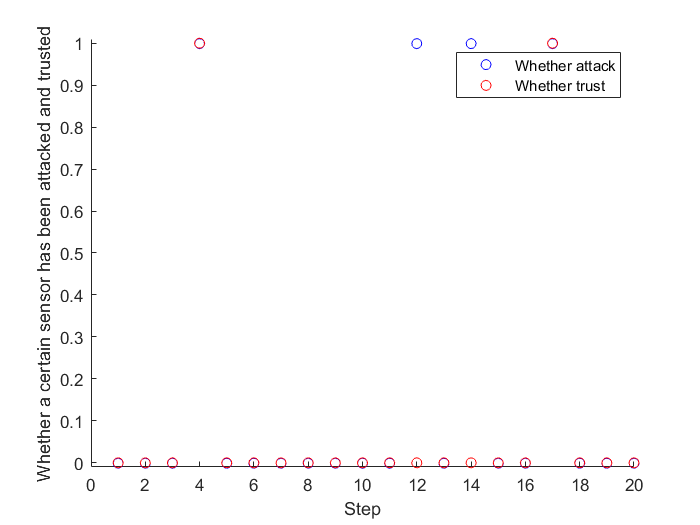


trust = zeros(1,time);
attach = zeros(1,time);

for i = 1:time
    attach(i) = randi([0, 1]); 
    if randi([0, 1]) == 0
        attach(i) = 0;
    end
    if randi([0, 1]) == 0
        trust(i) = attach(i);
    elseif randi([0, 1]) == 0
        trust(i) = attach(i);
    else
        trust(i) = randi([0, 1]);
    end
end

scatter(1:time,attach-0.001,'b')
hold on
scatter(1:time,trust,'r')
hold off
ylim([-0.01,1.01])
xlabel("Step")
ylabel("Whether a certain sensor has been attacked and trusted")
legend("Whether attack","Whether trust")